# ECM307-G01T02L03D - Atividade T3

%% Atividade T3 - Análise de Vogais
%% Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3


## Instruções

%%%% primeiro descomente a sessão de leitura
%%%% em seguida comente a sessão de análise
%%%% agora rode o código
%%%% depois comente a sessão de leitura e descomente a sessão de análise e
%%%% rode o código novamente

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas

## Leitura das vogais e armazenamento em arquivo Vogais.mat

% % prealocando
% a = cell(1,5);
% a{1,5} = [];
% 
% % prealocando
% e = cell(1,5);
% e{1,5} = [];
% 
% % prealocando
% i = cell(1,5);
% i{1,5} = [];
% 
% % prealocando
% o = cell(1,5);
% o{1,5} = [];
% 
% % prealocando
% u = cell(1,5);
% u{1,5} = [];
% 
% for ii = 1:5
% %%%% Leitura da vogal a
%     File = "a" + ii + ".wav";
%     
%     [Y,FS] = audioread(File);
%     
%     a{:,ii} = Y;
%     
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal e
%     File = "e" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
%     
% 
%     e{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal i
%     File = "i" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
% 
%     i{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal o
%     File = "o" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
% 
%     o{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal u
%     File = "u" + ii + ".wav";
%     
%     [Y,FS] = audioread(File);
% 
%     u{:,ii} = Y;
% 
% end
% save('Vogais.mat', 'a', 'e', 'i', 'o', 'u');

## Carregando o arquivo das vogais e as analisando

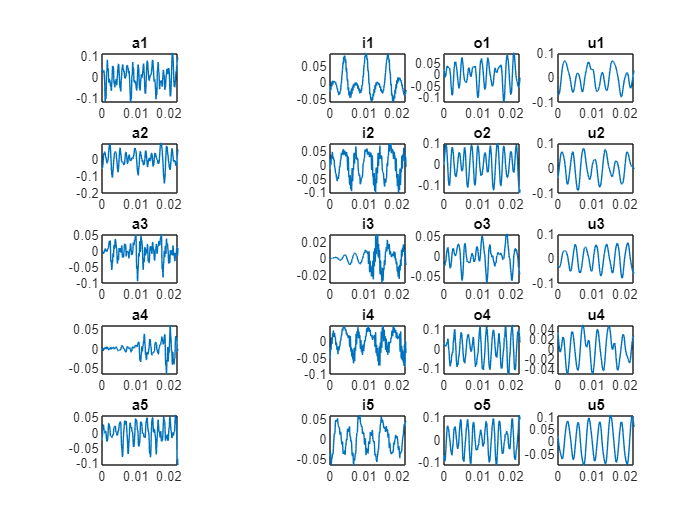

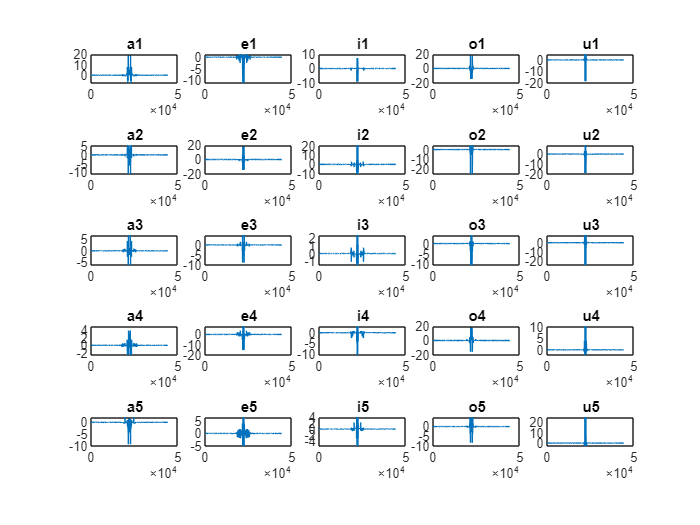

k = 0;
jj = 0;
% preallocation
a = cell(1,5);

% preallocation
e = cell(1,5);

% preallocation
i = cell(1,5);

% preallocation
o = cell(1,5);

% preallocation
u = cell(1,5);

load('Vogais.mat')
FS = 44100;
for ii = 1:5
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal a    
    %%%%% reduzindo o tamanho de a
    a{:,ii} = a{:,ii}(4000:4999);
    N       = length(a{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% plotando a série temporal
    figure(1);
    subplot(5,5,k);

    plot(tempo, a{:,ii});
    title("a" + ii);

    %% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);

    subplot(5,5,k);
    plot(freq,fftshift(fft(a{:,ii})));
    title("a" + ii);
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal e    
    %%%%% reduzindo o tamanho de e
    
    e{:,ii} = e{:,ii}(4000:4999);
    N       = length(e{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% plotando a série temporal
    subplot(5,5,k);

    plot(tempo, e{:,ii});
    title("e" + ii);
    
    %% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);

    subplot(5,5,k);
    plot(freq,fftshift(fft(e{:,ii})));
    title("e" + ii);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal i    
    %%%%% reduzindo o tamanho de i
    
    i{:,ii} = i{:,ii}(4000:4999);
    N       = length(i{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% plotando a série temporal
    figure(1);
    subplot(5,5,k);

    plot(tempo, i{:,ii});
    title("i" + ii);

    %% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);

    subplot(5,5,k);
    plot(freq,fftshift(fft(i{:,ii})));
    title("i" + ii);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal o    
    %%%%% reduzindo o tamanho de o
    
    o{:,ii} = o{:,ii}(4000:4999);
    N       = length(o{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% plotando a série temporal
    figure(1);
    subplot(5,5,k);

    plot(tempo, o{:,ii});
    title("o" + ii);

    %% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);

    subplot(5,5,k);
    plot(freq,fftshift(fft(o{:,ii})));
    title("o" + ii);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal u   
    %%%%% reduzindo o tamanho de u
    
    u{:,ii} = u{:,ii}(4000:4999);
    N       = length(u{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% plotando a série temporal
    figure(1);
    subplot(5,5,k);

    plot(tempo, u{:,ii});
    title("u" + ii);

    %% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);

    subplot(5,5,k);
    plot(freq,fftshift(fft(u{:,ii})));
    title("u" + ii);
end